## PEP_wp4_beh_exeriment 1

Start date: "2023-12-15"

The script performances the analysis of Experiment 1. It calculates the inter-subject RDM for the drawings and photos as well as the categorization performance and scene ratings. Then it compares them and computes the statistics. Expected output is Figure 2B and 2D.

You can run the script step-by-step or all at once.

### House keeping

% clear workspace
clear;
clc;

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

% if missing create a figure folder
if ~exist(fullfile(pwd,'figures'), 'dir')
    mkdir(fullfile(pwd,'figures'));
end


### Loading files

% details of subjects
cfg.subNums = [101:106,109:114,116:127,129:141]; %Excluded: 107,108,128 did not complete the full experiment, 115 had too poor drawing ability
cfg.n = length(cfg.subNums);
cfg.exp_num = 1;

% add scene categories and tasks
cfg.categories = {'bathroom', 'kitchen'};
cfg.tasks = {'categorization', 'typicality', 'familiarity', 'aesthetic', 'usability', 'complexity'};

% initialize data structure
d = struct;
%load('d.mat');
%load('cfg.mat');

% load files
d = load_files(cfg, d);

Loaded: 101
Loaded: 102
Loaded: 103
Loaded: 104
Loaded: 105
Loaded: 106
Loaded: 109
Loaded: 110
Loaded: 111
Loaded: 112
Loaded: 113
Loaded: 114
Loaded: 116
Loaded: 117
Loaded: 118
Loaded: 119
Loaded: 120
Loaded: 121
Loaded: 122
Loaded: 123
Loaded: 124
Loaded: 125
Loaded: 126
Loaded: 127
Loaded: 129
Loaded: 130
Loaded: 131
Loaded: 132
Loaded: 133
Loaded: 134
Loaded: 135
Loaded: 136
Loaded: 137
Loaded: 138
Loaded: 139
Loaded: 140
Loaded: 141


d.all_event_table.task = strrep(d.all_event_table.task, 'aesthetic', 'aesthetics');
cfg.tasks = strrep(cfg.tasks, 'aesthetic', 'aesthetics');

% load colormap
load('figures/colormaps.mat');
cfg.colormaps = colormaps;

% other standard configurations
cfg.FontName = 'Helvetica';
cfg.FontSize = 20;


### Timing

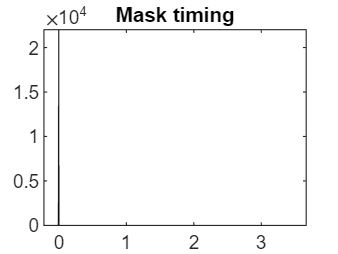

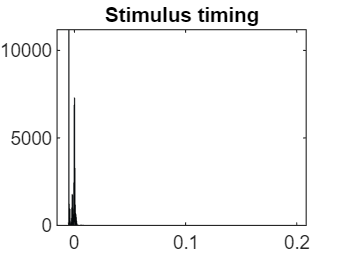

Timin is calculated


% to calculate and plot the timing
[timing, d]  = calculate_timing(d, cfg);

### Transfrom data (and trial and subject exclusion)

% make trial exclusion
d = trial_exclusion(d);

0 trials were < 0.1 s
363 trials were > 3 s
4 trials displayed stimulus on wrong frame
10 trials displayed mask on wrong frame
371 trials have been excluded
This equals 0.0056815 % of all trials



% transform data (adds a couple new subtables)
d = transform_data(d, cfg);

Data transformation has been performed




% make subject exclusion -
[d, cfg] = subject_exclusion(d, cfg);

Subject 101 meets all inclusion criteria
Subject 102 meets all inclusion criteria
Subject 103 meets all inclusion criteria
Subject 104 meets all inclusion criteria
Subject 105 meets all inclusion criteria
Subject 106 meets all inclusion criteria
Subject 109 meets all inclusion criteria


Subject 111 meets all inclusion criteria
Subject 112 meets all inclusion criteria
Subject 113 meets all inclusion criteria
Subject 114 meets all inclusion criteria
Subject 116 meets all inclusion criteria
Subject 117 meets all inclusion criteria
Subject 118 meets all inclusion criteria
Subject 119 meets all inclusion criteria
Subject 120 meets all inclusion criteria
Subject 121 meets all inclusion criteria
Subject 122 meets all inclusion criteria
Subject 123 meets all inclusion criteria
Subject 124 meets all inclusion criteria
Subject 125 meets all inclusion criteria
Subject 126 meets all inclusion criteria
Subject 127 meets all inclusion criteria
Subject 129 meets all inclusion criteria
Subject 130 meets all inclusion criteria
Subject 131 meets all inclusion criteria
Subject 132 meets all inclusion criteria


Subject 134 meets all inclusion criteria
Subject 135 meets all inclusion criteria
Subject 136 meets all inclusion criteria
Subject 137 meets all inclusion criteria
Subject 138 meets all inclusion criteria
Subject 139 meets all inclusion criteria
Subject 140 meets all inclusion criteria
Subject 141 meets all inclusion criteria
Data transformation is repeated because of subject exclusion
Data transformation has been performed



### Performance

% calculate performance
perf = make_perf(d, cfg);

Performance is calculated
Mean accuracy: 0.67979
Mean RT: 0.85316



### Inter-task correlations

Plotting and saving correlation plot for inter-subject level - bathroom


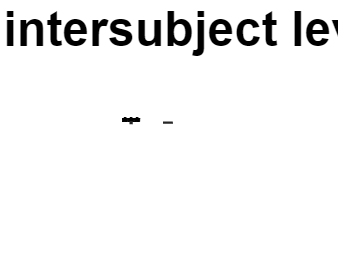

Plotting and saving correlation plot for inter-subject level - kitchen


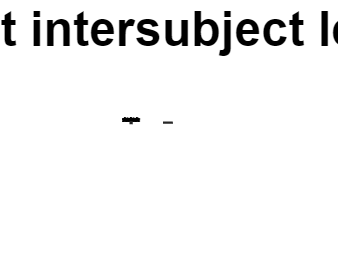

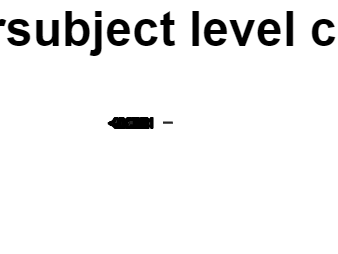

Plotting and saving correlation plot for inter-subject level - categoy avergaed
Plotting and saving correlation plot for own vs other analysis on task correaltions - bathroom


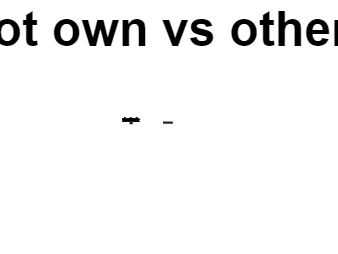

Plotting and saving correlation plot for own vs other analysis on task correaltions - kitchen


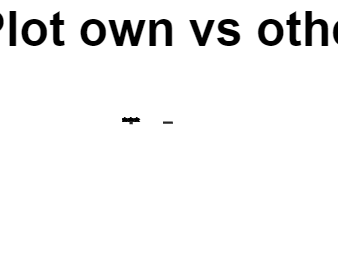

% calculate and plot the correlations of rating on
% population level

% preparation
cfg.variables_of_interest = {'IES', 'typicality','familiarity','aesthetics','usability','complexity'};
cfg.colormap = cfg.colormaps.white_zero2;
cfg.plot_rdm = true;
cfg.dissimilarity = true;

[rating_cor_plots, d] = plot_rating_cor(d, cfg);

### Intersubject correaltions

% calculate and plot the correlations of rating between subjects

% get variables of interest
cfg.variables_of_interest = {'mean_neg_RT', 'mean_trial_accuracy', 'IES', 'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
cfg.dissimilarity = true;
cfg.plot_rdm = false;

[cor_plots, d] = intersub_cor(d, cfg);

Plotting and saving inter-subject RDM for task:mean_neg_RT and bathroom
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and bathroom
Plotting and saving inter-subject RDM for task:IES and bathroom
Plotting and saving inter-subject RDM for task:typicality and bathroom
Plotting and saving inter-subject RDM for task:familiarity and bathroom
Plotting and saving inter-subject RDM for task:aesthetics and bathroom
Plotting and saving inter-subject RDM for task:usability and bathroom
Plotting and saving inter-subject RDM for task:complexity and bathroom
Plotting and saving inter-subject RDM for task:mean_neg_RT and kitchen
Plotting and saving inter-subject RDM for task:mean_trial_accuracy and kitchen
Plotting and saving inter-subject RDM for task:IES and kitchen
Plotting and saving inter-subject RDM for task:typicality and kitchen
Plotting and saving inter-subject RDM for task:familiarity and kitchen
Plotting and saving inter-subject RDM for task:aesthetics and kitchen
Plott

Plotting and saving correlation of task RDMs - bathroom
10% of permutations of IES are done
20% of permutations of IES are done
30% of permutations of IES are done
40% of permutations of IES are done
50% of permutations of IES are done
60% of permutations of IES are done
70% of permutations of IES are done
80% of permutations of IES are done
90% of permutations of IES are done
100% of permutations of IES are done
10% of permutations of typicality are done
20% of permutations of typicality are done
30% of permutations of typicality are done
40% of permutations of typicality are done
50% of permutations of typicality are done
60% of permutations of typicality are done
70% of permutations of typicality are done
80% of permutations of typicality are done
90% of permutations of typicality are done
100% of permutations of typicality are done
10% of permutations of familiarity are done
20% of permutations of familiarity are done
30% of permutations of familiarity are done
40% of permutations 

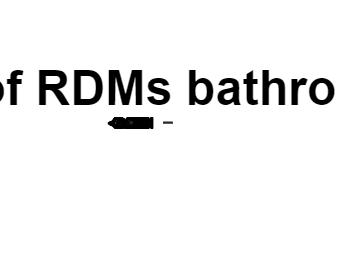

Plotting and saving correlation of task RDMs - kitchen
10% of permutations of IES are done
20% of permutations of IES are done
30% of permutations of IES are done
40% of permutations of IES are done
50% of permutations of IES are done
60% of permutations of IES are done
70% of permutations of IES are done
80% of permutations of IES are done
90% of permutations of IES are done
100% of permutations of IES are done
10% of permutations of typicality are done
20% of permutations of typicality are done
30% of permutations of typicality are done
40% of permutations of typicality are done
50% of permutations of typicality are done
60% of permutations of typicality are done
70% of permutations of typicality are done
80% of permutations of typicality are done
90% of permutations of typicality are done
100% of permutations of typicality are done
10% of permutations of familiarity are done
20% of permutations of familiarity are done
30% of permutations of familiarity are done
40% of permutations o

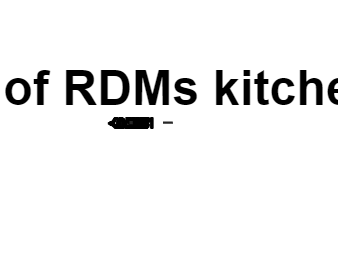

Compare categories


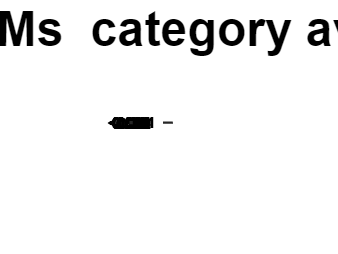

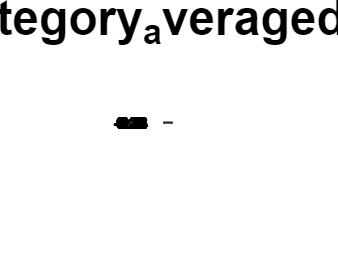

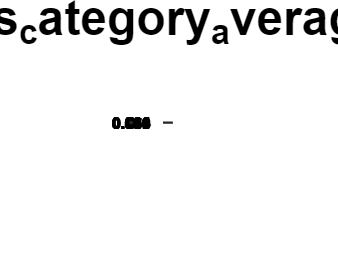

Length of labels do not match matrix dimensions




% calculate and plot the correlations between task RDMs and predictor RDMs

% define conditions
cfg.RDMs_of_interest = {'IES', 'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
cfg.predictor_RDMs = [];
cfg.mds = false;
cfg.colormap = cfg.colormaps.white_zero2;
cfg.rdm_name_prefix = 'RDM_of_RDMs_';
cfg.dissimilarity = false;
cfg.partial_cor = false;
cfg.plotting = true;
cfg.plot_rdm = true;
cfg.permutation_test = true;

% run correaltions 
[cor_plots, d] = RDM_of_RDMs(cor_plots, d, cfg);

### Correlate photos with DNN layer

% preparation
cfg.analysis_name = 'Photo_DNN_RDM';
cfg.correlation_type = 'spearman';
cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'early_late';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
[cfg.parent_dir, ~, ~] = fileparts(pwd);
images = struct;
cfg.file_format = 'png';
cfg.plot_rdm = true;
cfg.colormap = cfg.colormaps.photoColormap;
cfg.RDM_of_DNNS = true;
cfg.dissimilarity = true;

% The original script is commented out as the private photos can not be shared 
% Instead here we load photos IS-RDM directly so that the analysis can be performed
load(fullfile(pwd, 'batPhotoRDM.mat'))
d.DNN.(cfg.dnn).Photo_DNN_RDM.bathroom.subject_mean = batRDM;

load(fullfile(pwd, 'kitPhotoRDM.mat'))
d.DNN.(cfg.dnn).Photo_DNN_RDM.kitchen.subject_mean = kitRDM;

% make path
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities', 'pictures');

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 101_bat1.png
Loaded image: 101_bat2.png
Loaded image: 102_bat1.png
Loaded image: 102_bat2.png
Loaded image: 103_bat.png
Loaded image: 104_bat.png
Loaded image: 105_bat1.png
Loaded image: 105_bat2.png
Loaded image: 106_bat1.png
Loaded image: 106_bat2.png
Loaded image: 109_bat.png
Loaded image: 111_bat.png
Loaded image: 112_bat.png
Loaded image: 113_bat1.png
Loaded image: 113_bat2.png
Loaded image: 114_bat.png
Loaded image: 116_bat.png
Loaded image: 117_bat.png
Loaded image: 118_bat1.png
Loaded image: 118_bat2.png
Loaded image: 119_bat.png
Loaded image: 120_bat.png
Loaded image: 121_bat.png
Loaded image: 122_bat1.png
Loaded image: 122_bat2.png
Loaded image: 123_bat1.png
Loaded image: 123_bat2.png
Loaded image: 124_bat.png
Loaded image: 125_bat.png
Loaded image: 126_bat.png
Loaded image: 127_bat.png
Loaded image: 129_bat1.png
Loaded image: 129_bat2.png
Loaded image: 130_bat1.png
Loaded image: 130_bat2.png
Loaded image: 131_bat1.png
Loaded image: 131_bat2.png
Loaded image: 13

analysis Photo_DNN_RDM - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


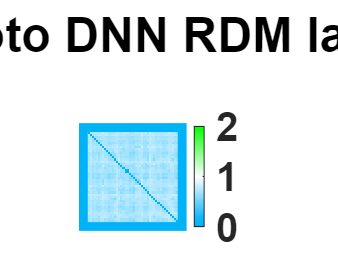

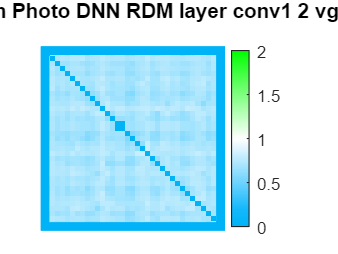

analysis Photo_DNN_RDM - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


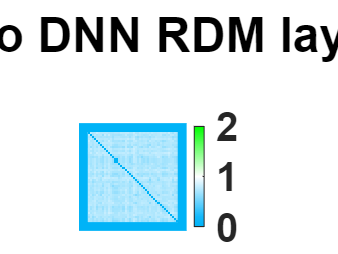

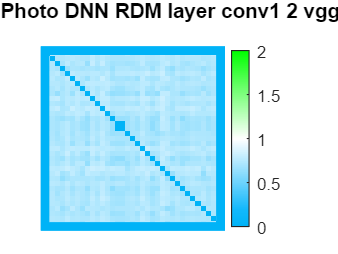

analysis Photo_DNN_RDM - layer #2 - category: bathroom
Length of labels do not match matrix dimensions


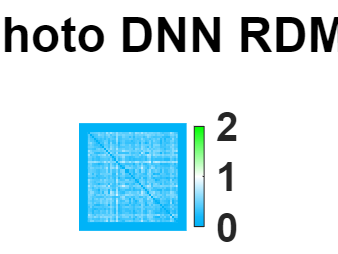

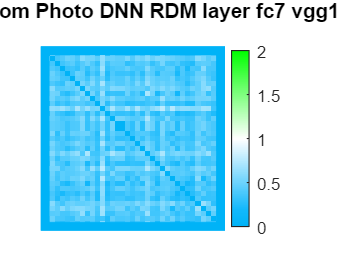

analysis Photo_DNN_RDM - layer #2 - category: kitchen
Length of labels do not match matrix dimensions


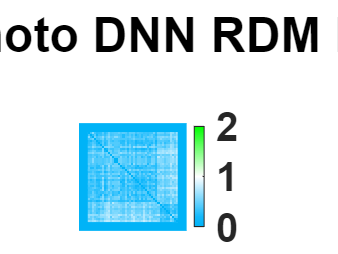

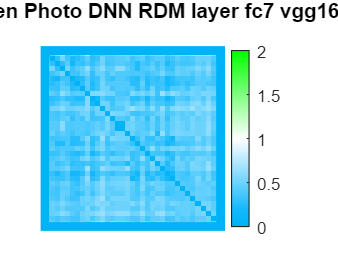


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);


% correlate similarities between subs with intersubject RDMs for each task
cfg.plot_rdm = false;
cfg.variables_of_interest = {'RT', 'accuracy',...
    'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
%plot_dnn_cor_by_layer(d, cfg);


### Correlate generated images of typical drawings with DNN layer

% preparation
cfg.analysis_name = 'Own_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'own';
cfg.plot_rdm = false;
cfg.colormap = cfg.colormaps.typDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities', 'drawings_draw3D', 'draw3D_images_exp1', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded image: 111_bat_gen3.png
Loaded image: 112_bat_gen1.png
Loaded image: 112_bat_gen2.png
Loaded image: 112_bat_gen3.png
Loaded image: 113_bat_gen1.png
Loaded image: 113_bat_gen2.png
Loaded image: 113_bat_gen3.png
Loaded image: 114_bat_gen1.png
Loaded image: 114_bat_gen2.png
Loaded i


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

analysis Own_drawing_DNN_RDM - layer #1 - category: bathroom
analysis Own_drawing_DNN_RDM - layer #1 - category: kitchen
analysis Own_drawing_DNN_RDM - layer #2 - category: bathroom
analysis Own_drawing_DNN_RDM - layer #2 - category: kitchen



% correlate similarities between subs with intersubject RDMs for each task
%plot_dnn_cor_by_layer(d, cfg);

### Correlate generated images of control images with DNN layer

% preparation
cfg.layer_type = 'late';
cfg.analysis_name = 'Control_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'control';
cfg.colormap = cfg.colormaps.ctrDrwColormap;
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'draw3D_images_exp1', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 101_bat_copy_gen1.png
Loaded image: 101_bat_copy_gen2.png
Loaded image: 101_bat_copy_gen3.png
Loaded image: 102_bat_copy_gen1.png
Loaded image: 102_bat_copy_gen2.png
Loaded image: 102_bat_copy_gen3.png
Loaded image: 103_bat_copy_gen1.png
Loaded image: 103_bat_copy_gen2.png
Loaded image: 103_bat_copy_gen3.png
Loaded image: 104_bat_copy_gen1.png
Loaded image: 104_bat_copy_gen2.png
Loaded image: 104_bat_copy_gen3.png
Loaded image: 105_bat_copy_gen1.png
Loaded image: 105_bat_copy_gen2.png
Loaded image: 105_bat_copy_gen3.png
Loaded image: 106_bat_copy_gen1.png
Loaded image: 106_bat_copy_gen2.png
Loaded image: 106_bat_copy_gen3.png
Loaded image: 109_bat_copy_gen1.png
Loaded image: 109_bat_copy_gen2.png
Loaded image: 109_bat_copy_gen3.png
Loaded image: 111_bat_copy_gen1.png
Loaded image: 111_bat_copy_gen2.png
Loaded image: 111_bat_copy_gen3.png
Loaded image: 112_bat_copy_gen1.png
Loaded image: 112_bat_copy_gen2.png
Loaded image: 112_bat_copy_gen3.png
Loaded image: 113_bat_copy_g


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

analysis Control_drawing_DNN_RDM - layer #1 - category: bathroom
analysis Control_drawing_DNN_RDM - layer #1 - category: kitchen



% correlate similarities between subs with intersubject RDMs for each task
%plot_dnn_cor_by_layer(d, cfg);

### Correlate original images of typical and control drawings with DNN layer

% preparation
cfg.analysis_name = 'Original_own_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'own';
cfg.file_format = 'jpg';
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'used_drawings_exp1', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 101_bat.jpg
Loaded image: 102_bat.jpg
Loaded image: 103_bat.jpg
Loaded image: 104_bat.jpg
Loaded image: 105_bat.jpg
Loaded image: 106_bat.jpg
Loaded image: 109_bat.jpg
Loaded image: 111_bat.jpg
Loaded image: 112_bat.jpg
Loaded image: 113_bat.jpg
Loaded image: 114_bat.jpg
Loaded image: 116_bat.jpg
Loaded image: 117_bat.jpg
Loaded image: 118_bat.jpg
Loaded image: 119_bat.jpg
Loaded image: 120_bat.jpg
Loaded image: 121_bat.jpg
Loaded image: 122_bat.jpg
Loaded image: 123_bat.jpg
Loaded image: 124_bat.jpg
Loaded image: 125_bat.jpg
Loaded image: 126_bat.jpg
Loaded image: 127_bat.jpg
Loaded image: 129_bat.jpg
Loaded image: 130_bat.jpg
Loaded image: 131_bat.jpg
Loaded image: 132_bat.jpg
Loaded image: 134_bat.jpg
Loaded image: 135_bat.jpg
Loaded image: 136_bat.jpg
Loaded image: 137_bat.jpg
Loaded image: 138_bat.jpg
Loaded image: 139_bat.jpg
Loaded image: 140_bat.jpg
Loaded image: 141_bat.jpg
Loaded image: 101_kit.jpg
Loaded image: 102_kit.jpg
Loaded image: 103_kit.jpg
Loaded image


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

analysis Original_own_drawing_DNN_RDM - layer #1 - category: bathroom
analysis Original_own_drawing_DNN_RDM - layer #1 - category: kitchen


Calculated correaltion of DNN layer representation of Original_own_drawing_DNN_RDM with task RDMs for bathroom
Calculated correaltion of DNN layer representation of Original_own_drawing_DNN_RDM with task RDMs for kitchen


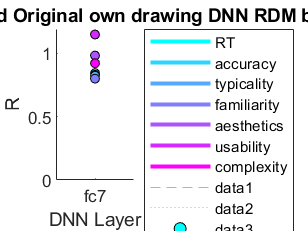


% correlate similarities between subs with intersubject RDMs for each task
plot_dnn_cor_by_layer(d, cfg);


%% Control drawings %%

% preparation
cfg.analysis_name = 'Original_control_drawing_DNN_RDM';
d.DNN.(cfg.dnn).(cfg.analysis_name) = struct;
drw_group = 'control';
cfg.folder_path = fullfile(cfg.parent_dir, 'image_similarities','drawings_draw3D', 'used_drawings_exp1', drw_group);

% load images
images.(cfg.analysis_name) = load_images(cfg);

Loaded image: 101_bat_copy.jpg
Loaded image: 102_bat_copy.jpg
Loaded image: 103_bat_copy.jpg
Loaded image: 104_bat_copy.jpg
Loaded image: 105_bat_copy.jpg
Loaded image: 106_bat_copy.jpg
Loaded image: 109_bat_copy.jpg
Loaded image: 111_bat_copy.jpg
Loaded image: 112_bat_copy.jpg
Loaded image: 113_bat_copy.jpg
Loaded image: 114_bat_copy.jpg
Loaded image: 116_bat_copy.jpg
Loaded image: 117_bat_copy.jpg
Loaded image: 118_bat_copy.jpg
Loaded image: 119_bat_copy.jpg
Loaded image: 120_bat_copy.jpg
Loaded image: 121_bat_copy.jpg
Loaded image: 122_bat_copy.jpg
Loaded image: 123_bat_copy.jpg
Loaded image: 124_bat_copy.jpg
Loaded image: 125_bat_copy.jpg
Loaded image: 126_bat_copy.jpg
Loaded image: 127_bat_copy.jpg
Loaded image: 129_bat_copy.jpg
Loaded image: 130_bat_copy.jpg
Loaded image: 131_bat_copy.jpg
Loaded image: 132_bat_copy.jpg
Loaded image: 134_bat_copy.jpg
Loaded image: 135_bat_copy.jpg
Loaded image: 136_bat_copy.jpg
Loaded image: 137_bat_copy.jpg
Loaded image: 138_bat_copy.jpg
Loaded i


% get correaltion of images from DNN
[d, cfg] = get_dnn_layer_similarity(d, images.(cfg.analysis_name), cfg);

analysis Original_control_drawing_DNN_RDM - layer #1 - category: bathroom
analysis Original_control_drawing_DNN_RDM - layer #1 - category: kitchen


Calculated correaltion of DNN layer representation of Original_control_drawing_DNN_RDM with task RDMs for bathroom
Calculated correaltion of DNN layer representation of Original_control_drawing_DNN_RDM with task RDMs for kitchen


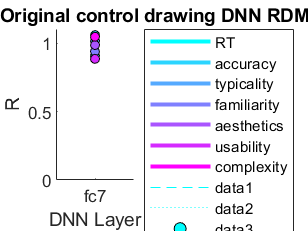


% correlate similarities between subs with intersubject RDMs for each task
plot_dnn_cor_by_layer(d, cfg);

### Drawing similarity of human raters

% load similarity ratings by humans
d = load_similarity_ratings(d, cfg)

Loaded: sub-001 bathroom
Loaded: sub-001 kitchen
Loaded: sub-002 bathroom
Loaded: sub-002 kitchen
Loaded: sub-003 bathroom
Loaded: sub-003 kitchen
Loaded: sub-004 bathroom
Loaded: sub-004 kitchen
Loaded: sub-005 bathroom
Loaded: sub-005 kitchen
Loaded: sub-007 bathroom
Loaded: sub-007 kitchen
Loaded: sub-008 bathroom
Loaded: sub-008 kitchen
Loaded: sub-009 bathroom
Loaded: sub-009 kitchen
Loaded: sub-010 bathroom
Loaded: sub-010 kitchen
Loaded: sub-011 bathroom
Loaded: sub-011 kitchen
Loaded: sub-012 bathroom
Loaded: sub-012 kitchen
Loaded: sub-013 bathroom
Loaded: sub-013 kitchen
Loaded: sub-014 bathroom
Loaded: sub-014 kitchen
Loaded: sub-015 bathroom
Loaded: sub-015 kitchen
Loaded: sub-016 bathroom
Loaded: sub-016 kitchen
Loaded: sub-017 bathroom
Loaded: sub-017 kitchen
Loaded: sub-018 bathroom
Loaded: sub-018 kitchen
Loaded: sub-019 bathroom
Loaded: sub-019 kitchen
Loaded: sub-020 bathroom
Loaded: sub-020 kitchen
Loaded: sub-021 bathroom
Loaded: sub-021 kitchen


d = struct with fields:
         all_event_table: [61515×25 table]
                raw_data: [65300×25 table]
         exlcuded_trials: 371
    prop_exlcuded_trials: 0.0057
              cate_table: [41786×25 table]
               typ_table: [3500×25 table]
               fam_table: [3500×25 table]
               aes_table: [3500×25 table]
               use_table: [3500×25 table]
               com_table: [3500×25 table]
            img_id_table: [3500×13 table]
       just_img_id_table: [100×21 table]
              within_sub: [1×1 struct]
             RDM_of_RDMs: [1×1 struct]
               own_other: [1×1 struct]
           RDM_pwc_table: [8×3 table]
            bathroom_RDM: [1×1 struct]
             kitchen_RDM: [1×1 struct]
          RDM_of_RDM_pwc: [1×1 struct]
                     DNN: [1×1 struct]
        all_rating_table: [25000×16 table]
            drw_id_table: [1190×8 table]
    drw_id_table_wo_cate: [595×7 table]


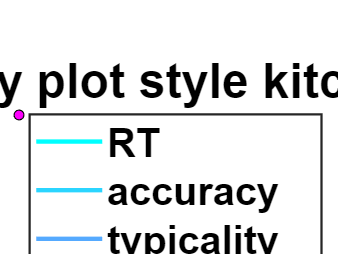


% make drawing RDM and plot them
cfg.dissimilarity = true;
d = make_drawing_RDM(d, cfg);


% calculate consisteny in ratings
d = human_ratings_consitency(d, cfg);

Median between raters correlation of content for bathroom is: 0.0066942
Median between raters correlation of style for bathroom is: 0.00032054
Median between raters correlation of content for kitchen is: -0.011474
Median between raters correlation of style for kitchen is: -0.00021165


### Compare the intersubject task RDMs to the predictor RDMs

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of typicality bathroom is done
20% of permutations of typicality bathroom is done
30% of permutations of typicality bathroom is done
40% of permutations of typicality bathroom is done
50% of permutations of typicality bathroom is done
60% of permutations of typicality bathroom is done
70% of permutations of typicality bathroom is done
80% of permutations of typicality bathroom is done
90% of permutations of typicality bathroom is done
100% of permutations of typicality bathroom is done
Compare inter-subject RDM of typicality with correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of typicality kitchen is done
20% of permutations of typicality kitchen is done
30% of permutations of typicality kitchen is done
40% of permutations of typicality kitchen is done
50% of permutations of typicality kitchen is done
60% of permutations of typicality kit

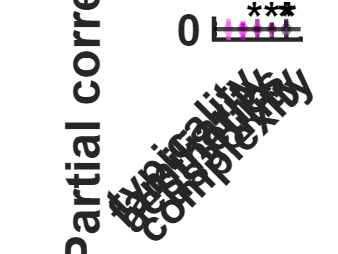

% preparation
cfg.partial_cor = true;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late', ...
    'Photos vgg16_imagenet Late'};
cfg.predictor_RDMs = {'generated_images_own_dnn_layer_late', 'generated_images_ctr_dnn_layer_late', ...
    'photos_dnn_layer_late'};
cfg.tasks_of_interest = {'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
cfg.dnns = {'vgg16_imagenet'};
cfg.partial_correlation_type = 'pearson';
cfg.plot_type = 'violin';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 100;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ylim = [-0.4, 0.4];
cfg.task_plotting = true;
cfg.plotting_predictors = 1;
cfg.plott_gap = 0; 

cfg.tasks_of_interest = {'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES bathroom is done
20% of permutations of IES bathroom is done
30% of permutations of IES bathroom is done
40% of permutations of IES bathroom is done
50% of permutations of IES bathroom is done
60% of permutations of IES bathroom is done
70% of permutations of IES bathroom is done
80% of permutations of IES bathroom is done
90% of permutations of IES bathroom is done
100% of permutations of IES bathroom is done
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES kitchen is done
20% of permutations of IES kitchen is done
30% of permutations of IES kitchen is done
40% of permutations of IES kitchen is done
50% of permutations of IES kitchen is done
60% of permutations of IES kitchen is done
70% of permutations of IES kitchen is done
80% of permutations of IES kitchen is done
90% of permutations 

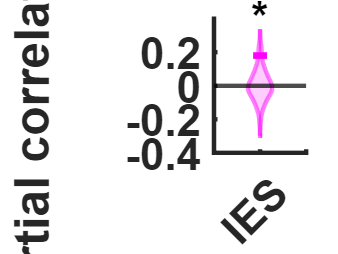


cfg.tasks_of_interest = {'IES'};
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES bathroom is done
20% of permutations of IES bathroom is done
30% of permutations of IES bathroom is done
40% of permutations of IES bathroom is done
50% of permutations of IES bathroom is done
60% of permutations of IES bathroom is done
70% of permutations of IES bathroom is done
80% of permutations of IES bathroom is done
90% of permutations of IES bathroom is done
100% of permutations of IES bathroom is done
Compare inter-subject RDM of IES with correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of IES kitchen is done
20% of permutations of IES kitchen is done
30% of permutations of IES kitchen is done
40% of permutations of IES kitchen is done
50% of permutations of IES kitchen is done
60% of permutations of IES kitchen is done
70% of permutations of IES kitchen is done
80% of permutations of IES kitchen is done
90% of permutations 

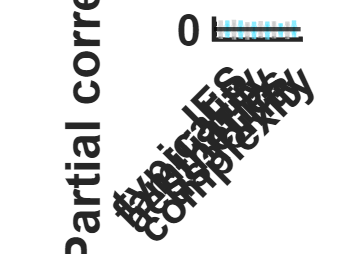


cfg.plotting_predictors = [2,3];
cfg.tasks_of_interest = {'IES', 'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'};
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

Use different predictors

% preparation
cfg.analysis_names = {'Own_drawing_DNN_RDM', 'Control_drawing_DNN_RDM', 'Photo_DNN_RDM'}

cfg = struct with fields:
                     subNums: [101 102 103 104 105 106 109 111 112 113 114 116 117 118 119 120 121 122 123 124 125 126 127 129 130 131 132 134 135 136 137 138 139 140 141]
                           n: 35
                     exp_num: 1
                  categories: {'bathroom'  'kitchen'}
                       tasks: {'categorization'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
                   colormaps: [1×1 struct]
                    FontName: 'Helvetica'
                    FontSize: 20
       variables_of_interest: {'RT'  'accuracy'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
                    colormap: [256×3 double]
                    plot_rdm: 0
               dissimilarity: 1
            RDMs_of_interest: {'IES'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
              predictor_RDMs: {'generated_images_own_dnn_layer_early'  'generated_images_ctr_dnn_layer_early' 

d = get_object_sim(d, cfg);

Computed pairwise object overlap similarity matrix for:
bathroom - Own_drawing_DNN_RDM
Computed pairwise object overlap similarity matrix for:
bathroom - Control_drawing_DNN_RDM
Computed pairwise object overlap similarity matrix for:
bathroom - Photo_DNN_RDM
Computed pairwise object overlap similarity matrix for:
kitchen - Own_drawing_DNN_RDM
Computed pairwise object overlap similarity matrix for:
kitchen - Control_drawing_DNN_RDM
Computed pairwise object overlap similarity matrix for:
kitchen - Photo_DNN_RDM
Done.


d = load_description_rdms(d, cfg);
d = compute_spatial_coherence_rdms(d, cfg);

Computed pairwise contrast similarity matrix for:
bathroom - Own_drawing_DNN_RDM
Computed pairwise contrast similarity matrix for:
bathroom - Control_drawing_DNN_RDM
Computed pairwise contrast similarity matrix for:
bathroom - Photo_DNN_RDM
Computed pairwise contrast similarity matrix for:
kitchen - Own_drawing_DNN_RDM
Computed pairwise contrast similarity matrix for:
kitchen - Control_drawing_DNN_RDM
Computed pairwise contrast similarity matrix for:
kitchen - Photo_DNN_RDM
Done.


cfg.partial_cor = true;
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'generated_images_own_dnn_layer_early', 'generated_images_ctr_dnn_layer_early', ...
    'photos_dnn_layer_early'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.tasks_of_interest = {'IES', 'typicality', 'familiarity', 'aesthetics', 'usability', 'complexity'}

cfg = struct with fields:
                     subNums: [101 102 103 104 105 106 109 111 112 113 114 116 117 118 119 120 121 122 123 124 125 126 127 129 130 131 132 134 135 136 137 138 139 140 141]
                           n: 35
                     exp_num: 1
                  categories: {'bathroom'  'kitchen'}
                       tasks: {'categorization'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
                   colormaps: [1×1 struct]
                    FontName: 'Helvetica'
                    FontSize: 20
       variables_of_interest: {'RT'  'accuracy'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
                    colormap: [256×3 double]
                    plot_rdm: 0
               dissimilarity: 1
            RDMs_of_interest: {'IES'  'typicality'  'familiarity'  'aesthetics'  'usability'  'complexity'}
              predictor_RDMs: {'generated_images_own_dnn_layer_early'  'generated_images_ctr_dnn_layer_early' 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of familiarity with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of 

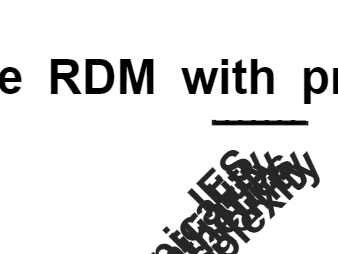

cfg.plot_type = 'bar';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.partial_correlation_type = 'Spearman';

% plot typical drawings (Figure 3)
cfg.filter_predictors = {'typical', 'own'};

cfg.dnns = {'vgg16_imagenet'};
cfg.plot_names = cfg.tasks_of_interest;
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of familiarity with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of 

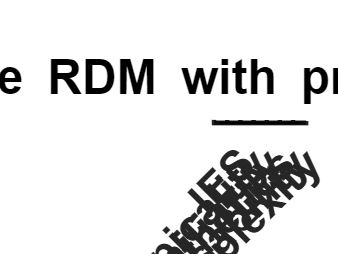


cfg.dnns = {'ce'};
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of familiarity with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of 


cfg.dnns = {'sc'};
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of familiarity with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of 


cfg.dnns = {'objectCount'};
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);

 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of IES with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of typicality with partial correaltion of predictor RDMs - kitchen
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of familiarity with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
Running 100 permutations...
Compare inter-subject RDM of 


cfg.dnns = {'objectSim'};
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);


%cfg.dnns = {'descSim'};
d = compare_task_RDMs_to_multiple_predictor_RDMs(d, cfg);

### **Compare different DNNs **

% check how much the similarity between the networks correlate

% preparation
cfg.layer_type = 'late';
cfg.plot_rdm = false;
cfg.analysis_names = {'Own_drawing_DNN_RDM', 'Control_drawing_DNN_RDM','Photo_DNN_RDM'...
    'Original_own_drawing_DNN_RDM','Original_control_drawing_DNN_RDM'};
cfg.dnns = {'clip','dino','googlenet_places365','vggnet16_places365','vgg16_imagenet'};

[d, images] = dnn_network_similarity(d, images, cfg);


### How different DNNs can predict human ratings

% check how much the similarity of different the networks correlate with
% human ratings

% preparation
cfg.partial_cor = false;
cfg.RDM_to_partial_out = [];
cfg.dnns = {'clip','dino','googlenet_places365','vggnet16_places365','vgg16_imagenet'};
cfg.plot_rdm = false;
cfg.add_legend = false;
cfg.xaxis_labels = true;
cfg.order_predictors = true;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ylim = [-.15, .61];
cfg.correlation_type = 'Pearson';
cfg.add_legend = false;
cfg.task_plotting = false;
cfg.dissimilarity = false;

% compare different DNN similarity measures of own drawings with human
% raters
cfg.tasks_of_interest = {'typical_drawing_content'};
cfg.predictor_RDMs = {'generated_images_own_dnn_layer_late','original_images_own_dnn_layer_late',...
    'own_clip_model', 'original_own_clip_model', 'own_dino_model', 'original_own_dino_model'};
cfg.plotting_predictors = 1:numel(cfg.predictor_RDMs);

cfg.save_name = 'compare_own_drw_against_human_rating';
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

% compare different DNN similarity measures of control drawings with human
% raters
cfg.tasks_of_interest = {'typical_drawing_style'};
cfg.predictor_RDMs = {'generated_images_ctr_dnn_layer_late','original_images_ctr_dnn_layer_late',...
    'control_clip_model', 'original_control_clip_model', 'control_dino_model', 'original_control_dino_model'};

cfg.save_name = 'compare_ctr_drw_against_human_rating';
d = compare_task_RDMs_to_predictor_RDMs(d, cfg);
